# Lab 2 - Non-linear Fitting

Harshal B. Varpe

clc;
clear all;
%Take user input about data set. User input is case sensitive.%
usr_input = input("Please enter the data set A, B or C : ","s")

usr_input = 'A'

if strcmp(usr_input,"A") | strcmp(usr_input,"B") | strcmp(usr_input,"C")
    fprintf("Entered value is %s", usr_input)
else
    fprintf("Please input A,B or C !")
end

Entered value is A

if strcmp(usr_input,"A")
    data = readtable("A.txt");
elseif strcmp(usr_input,"B")
    data = readtable("B.txt");
elseif strcmp(usr_input,"C")
    data = readtable("C.txt");
else
    fprintf("Something went wrong!")
end

% Take initial value from user %
a0 = input("Please enter the initial guess : ");

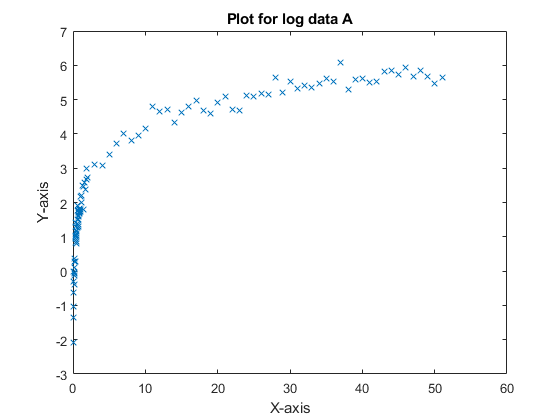

% Plotting the chosen data set
plot(data.Var1,data.Var2,"x")
t = "Plot for log data " + usr_input;
title(t)
xlabel("X-axis")
ylabel("Y-axis")
hold on

% Actual calculation of the Loop
x = data.Var1;
y = data.Var2;
p_max = 30000;
for p=1:1:p_max
    f_an = 0;
    f_pan = 0;
    for q=1:1:length(x)
        f_an = f_an + ((y(q)-log(a0*x(q)))*(1/a0));
        f_pan = f_pan + ((-1/(a0^2)))*(y(q) - log(a0*x(q))+ 1);
    end
    a1 = a0 -(f_an/f_pan);
    fprintf("a0 is %0.5f  a1 is %0.5f \n",a0,a1)
    diff = abs(a0-a1);
    if diff < 0.000001
        fprintf("Convergence reached!!")
        break;
    elseif diff > p_max
        fprintf("Wrong guess! Possible Diveregence!")
        break;
    end
    a0 = a1;
end

a0 is 1.00000  a1 is 1.65562 
a0 is 1.65562  a1 is 2.62130 
a0 is 2.62130  a1 is 3.89150 
a0 is 3.89150  a1 is 5.26424 
a0 is 5.26424  a1 is 6.29291 
a0 is 6.29291  a1 is 6.67353 
a0 is 6.67353  a1 is 6.71104 
a0 is 6.71104  a1 is 6.71136 
a0 is 6.71136  a1 is 6.71136 


Convergence reached!!


fprintf("No. of iterations is : %d. ",p)

No. of iterations is : 9. 

fprintf("The final value of unknown a is %0.5f ",a0)

The final value of unknown a is 6.71136 

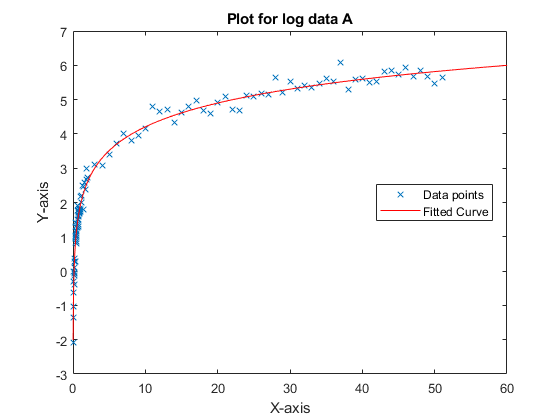

%Plotting the curve
r=0:0.02:100;
y_1 = log(a0.*r);

plot(r,y_1,"r-")
xlim([0 60])
legend("Data points","Fitted Curve","Location","best")